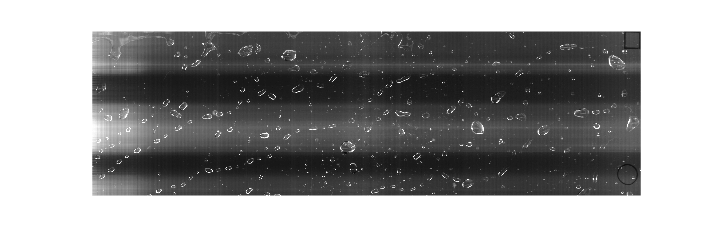

% Get image for analyzing
source_img = im2gray(imread('_IMAG0003.JPG'));
imshow(source_img)

relImg = double(source_img)./256;

### Radon transformation

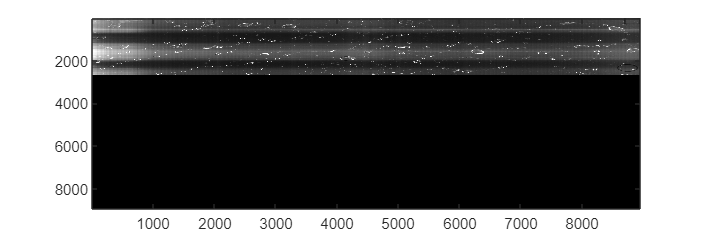

I = zeros(8960,8960); % 16384*16384

I(1:2688,1:8960) = relImg;
imagesc(I,[0 1]);
colormap(gray);

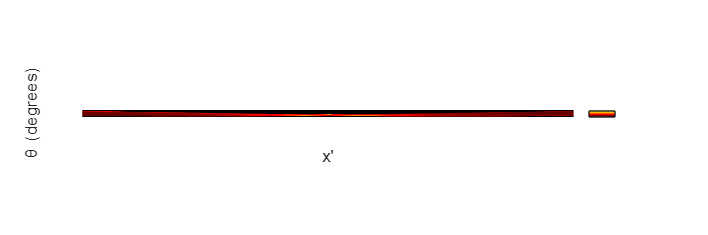


theta = 0:179;
[R,xp] = radon(I,theta);

imshow(R,[],'Ydata',theta,'Xdata',xp,'InitialMagnification','fit')
ylabel('\theta (degrees)')
xlabel('x''')
colormap(gca,hot), colorbar


iptsetpref('ImshowAxesVisible','off')

### Save only necessary angles

% angle range
delta_angle = 1;

R_hor = R;
R_vert = R;

R_hor(:,1:89) = 0;
R_hor(:,91:180) = 0;

R_vert(:,2:180) = 0;

hor_line_img = iradon(R_hor,theta);
vert_line_img = iradon(R_vert,theta);

vert_line_img =    -2.4255    2.4358    1.1158    0.7222    0.4849    0.4150    0.2862    0.2191    0.1640    0.1044    0.0948    0.0865    0.0725    0.0886    0.1071    0.1341    0.1233    0.2051    0.1600    0.1233    0.0753    0.0427    0.0256    0.0276    0.0149    0.0333    0.0481    0.0993    0.1449    0.1616    0.1433    0.1128    0.1247   -0.0176    0.0160    0.0079   -0.0022    0.0019    0.0174    0.0344    0.0166    0.1417    0.1301    0.1371    0.1128    0.0630    0.0076   -0.0267   -0.0349   -0.0258
   -2.4255    2.4358    1.1158    0.7222    0.4849    0.4150    0.2862    0.2191    0.1640    0.1044    0.0948    0.0865    0.0725    0.0886    0.1071    0.1341    0.1233    0.2051    0.1600    0.1233    0.0753    0.0427    0.0256    0.0276    0.0149    0.0333    0.0481    0.0993    0.1449    0.1616    0.1433    0.1128    0.1247   -0.0176    0.0160    0.0079   -0.0022    0.0019    0.0174    0.0344    0.0166    0.1417    0.1301    0.1371    0.1128    0.0630    0.0076   -0.0267   

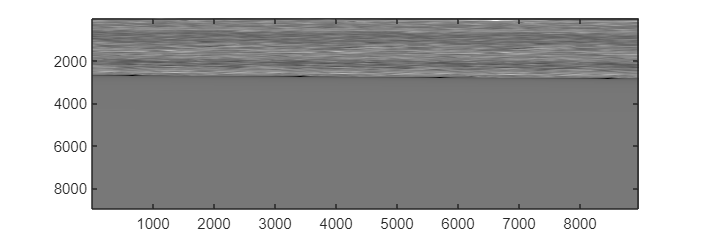

imagesc(hor_line_img);

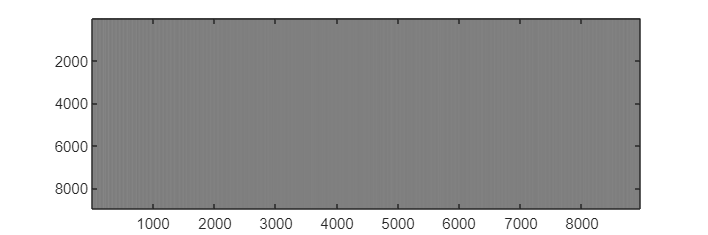

imagesc(vert_line_img);

### Image enchancement

vert_cut_line_img = vert_line_img(1:2688,1:8960);
min_val = min(vert_cut_line_img(:))

min_val = -2.4255

max_val = max(vert_cut_line_img(:))

max_val = 2.4358

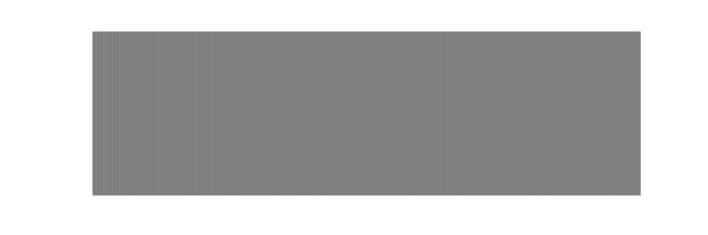

vert_grayscale_img = uint8(255/(max_val-min_val)*(vert_cut_line_img-min_val));
imshow(vert_grayscale_img)


hor_cut_line_img = hor_line_img(1:2688,1:8960);
min_val = min(hor_cut_line_img(:))

min_val = -0.0902

max_val = max(hor_cut_line_img(:))

max_val = 0.1723

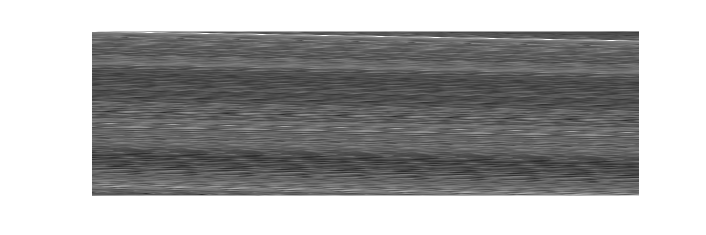

hor_grayscale_img = uint8(255/(max_val-min_val)*(hor_cut_line_img-min_val));
imshow(hor_grayscale_img)

### Image binarization

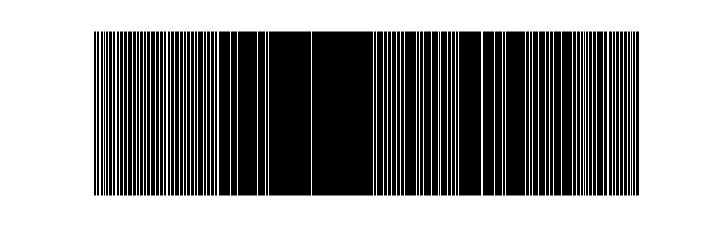

threshold = 129;
% relative intensity
relThresh = threshold/256;

vert_bw = imbinarize(vert_grayscale_img,relThresh);
imshow(vert_bw)

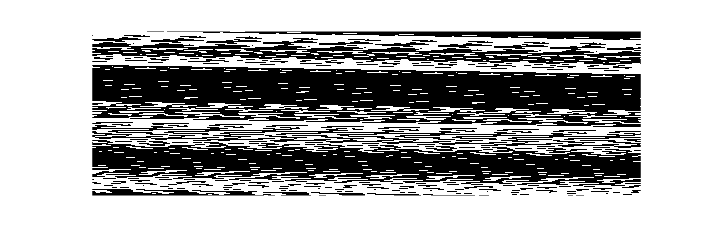


threshold = 100;
% relative intensity
relThresh = threshold/256;

hor_bw = imbinarize(hor_grayscale_img,relThresh);
imshow(hor_bw)

Extract lines from image

mean_pix = uint8(mean(source_img,'all'))

mean_pix = uint8
65

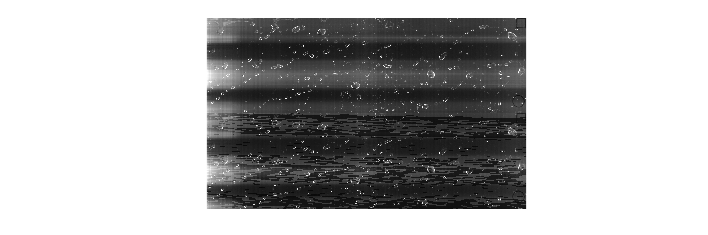

% mean_pix = 0
new_image = source_img;
new_image(hor_bw) = wiener2(new_image(hor_bw));
montage({source_img, new_image},'Size', [2 1]);

imshow(imabsdiff(source_img,new_image))

img = new_image;

%mean(source_img,'all')

% Morphological structuring element - disk
% disk mask decomposition
%closeRadius = 40;
%decomposition = 8;
%se = strel('disk', closeRadius, decomposition);

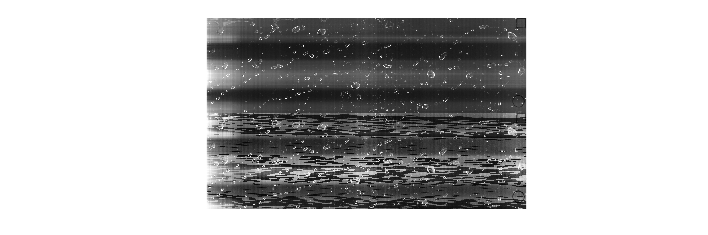

% img = source_img
img = wiener2(new_image);
img = adapthisteq(img);
montage({source_img, img},'Size', [2 1]);

% level = multithresh(img);

threshold = 180;
% relative intensity
relThresh = threshold/256;

vert_bw = imbinarize(img,relThresh);
vert_bw = imclearborder(vert_bw);
% close mask with disk
vert_bw = imclose(vert_bw, se);

Unrecognized function or variable 'se'.

vert_bw = imfill(vert_bw, 'holes');
imshow(vert_bw)
%binImg = edge(bw, 'Canny', relThresh);
%imshow(binImg)